## MILESTONE 2: VIOLIN & PIANO ANALYSIS

Syed Sualeh Abbas 10303, Syed Muhammad Haider Zaidi 10270

## Analyze their frequency content and explore some interesting aspects in line with Task A (parts 1 to 7)

clear; close all; clc;

%% PART 1: DATA LOADING & STANDARDIZATION
% Loading violin and piano recordings
[v_x, v_fs] = audioread('sualeh-violin.mp3');
[p_x, p_fs] = audioread('haider-piano.mp3');

% Organizing Violin and Piano into a simple structure
% We convert to mono using mean(x, 2) to ensure the signal is a single vector
instr(1).name = 'Violin';
instr(1).x = mean(v_x, 2); 
instr(1).fs = v_fs;

instr(2).name = 'Piano';
instr(2).x = mean(p_x, 2); 
instr(2).fs = p_fs;

fprintf('--- PART 1: SIGNAL STATS ---\n');

--- PART 1: SIGNAL STATS ---


for i = 1:2
    dur = length(instr(i).x) / instr(i).fs;
    fprintf('%s: %.2f seconds at %d Hz\n', instr(i).name, dur, instr(i).fs);
end

Violin: 32.01 seconds at 44100 Hz
Piano: 9.39 seconds at 44100 Hz


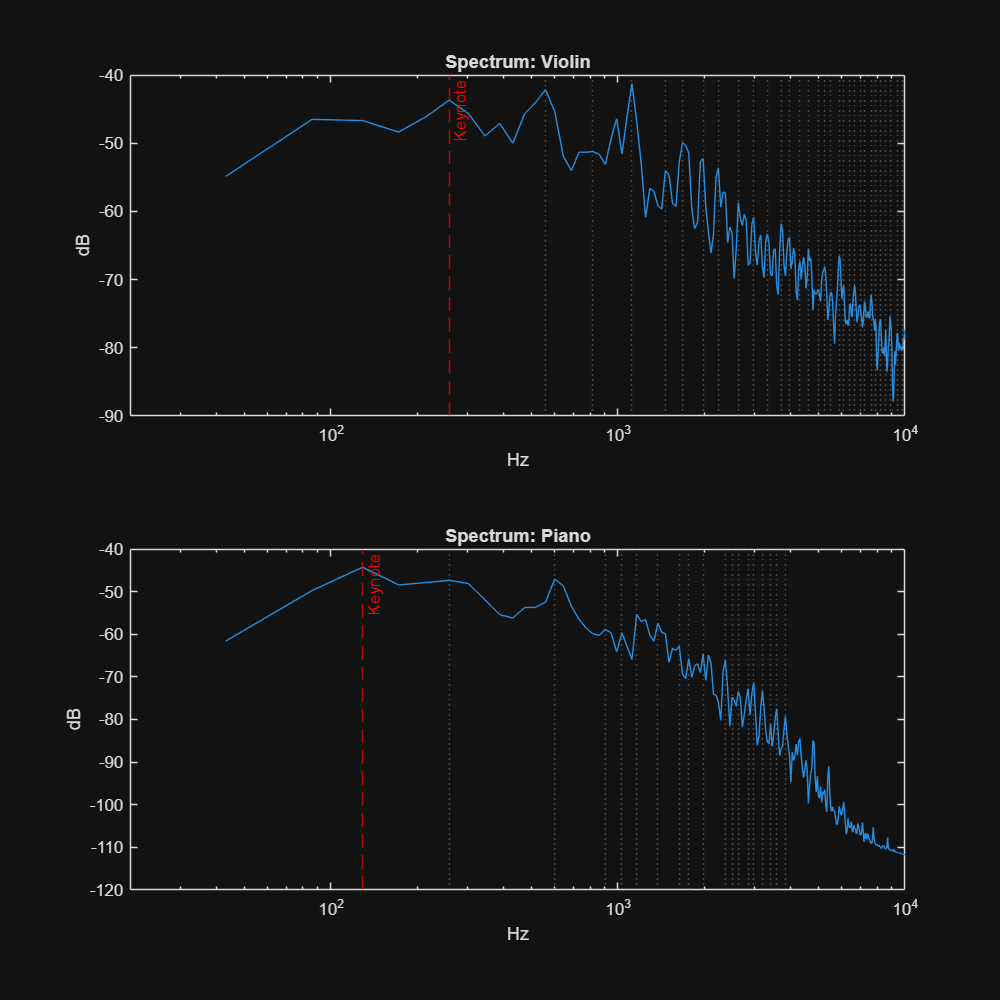

The Keynote frequency for Violin is: 258.40 Hz


-------------------------------------------


Number of overtones detected for Violin: 34



--- Violin Harmonic Analysis ---


    Harmonic_k    Ideal_Hz    Detected_Hz    Perc_Error
    __________    ________    ___________    __________

         1          258.4        258.4              0  
         2          516.8       559.86         8.3333  
         3          775.2       818.26         5.5556  
         4         1033.6       1119.7         8.3333  
         6         1550.4       1464.3         5.5556  
         7         1808.8       1679.6         7.1429  
         8         2067.2       1981.1         4.1667  
         9         2325.6       2239.5         3.7037  
        10           2584       2627.1         1.6667  
        12         3100.8       2971.6         4.1667  
        13         3359.2       3316.1         1.2821  
        14         3617.6       3703.7          2.381  
        15           3876       3962.1         2.2222  
        17         4392

The Keynote frequency for Piano is: 129.20 Hz


-------------------------------------------


Number of overtones detected for Piano: 18



--- Piano Harmonic Analysis ---


    Harmonic_k    Ideal_Hz    Detected_Hz    Perc_Error
    __________    ________    ___________    __________

         1          129.2        129.2              0  
         2          258.4        258.4              0  
         5            646       602.93         6.6667  
         7         904.39       904.39              0  
         8         1033.6       1033.6              0  
         9         1162.8       1162.8              0  
        11         1421.2       1378.1         3.0303  
        13         1679.6       1636.5         2.5641  
        14         1808.8       1765.7          2.381  
        15           1938       1981.1         2.2222  
        18         2325.6       2368.7         1.8519  
        19         2454.8       2497.9         1.7544  
        20           2584       2627.1         1.6667  
        22         2842

%% PART 2, 3 & 4: SPECTRAL ANALYSIS & ERRORS
figure('Name', 'Milestone 2 Spectra', 'Position', [100, 100, 800, 800]);

for i = 1:2
    % Generating Power Spectral Density using Welch's method
    [pxx, f] = pwelch(instr(i).x, hamming(1024), [], [], instr(i).fs);
    P_db = 10*log10(pxx + eps);
    
    % Now we will Find the Keynote (Fundamental Frequency f0) for violin
    % and piano
    % We search specifically in the 50-500Hz as its the general range.
    range = (f >= 50 & f <= 500);
    [~, idx] = max(P_db(range));
    f_sub = f(range);
    f0 = f_sub(idx);
    instr(i).keynote = f0;
 

    
    % Identifying Overtones
    % We look for peaks at least 40dB above the floor and separated by ~f0
    [~, locs] = findpeaks(P_db, f, 'MinPeakHeight', max(P_db)-40, 'MinPeakDistance', f0*0.8);
    overtones = locs(locs > f0 * 1.1); % this will exculde the keytone, so its not counted as one of the overtones
    fprintf('The Keynote frequency for %s is: %.2f Hz\n', instr(i).name, f0);
    fprintf('-------------------------------------------\n');
    % This counts how many overtones were detected for the current instrument
    num_overtones = length(overtones);
    fprintf('Number of overtones detected for %s: %d\n', instr(i).name, num_overtones);

    
    % Plotting
    subplot(2,1,i);
    semilogx(f, P_db); hold on; grid off;
    xline(f0, 'r--', 'Keynote');
    if ~isempty(overtones)
        xline(overtones, ':', 'Color', [0.5 0.5 0.5], 'Alpha', 0.5); 
    end
    title(['Spectrum: ', instr(i).name]);
    xlim([20, 10000]); xlabel('Hz'); ylabel('dB');


    % Creating the Error Table, to check percentage of error in integral
    % multiple frequencies and overtones. 
    K = [1; round(overtones ./ f0)];
    Theo = K .* f0;
    Actual = [f0; overtones];
    Err = (abs(Actual - Theo) ./ Theo) * 100;
    %this will calculate for all peaks not for just overtones. so in table
    %more values the overtones can be observed
    T = table(K, Theo, Actual, Err, 'VariableNames', ...
        {'Harmonic_k', 'Ideal_Hz', 'Detected_Hz', 'Perc_Error'});
    
    fprintf('\n--- %s Harmonic Analysis ---\n', instr(i).name);
    disp(T);
end

%% PART 5: NOISE ANALYSIS (50Hz vs 60Hz)
fprintf('\n--- PART 5: MAINS HUM CHECK ---\n');


--- PART 5: MAINS HUM CHECK ---


for i = 1:2
    [pxx, f] = pwelch(instr(i).x, hamming(2048), [], [], instr(i).fs);
    P = 10*log10(pxx + eps);
    
    % Grab the max power near 50Hz (Pakistani Grid) and 60Hz.
    p50 = max(P(f > 48 & f < 52));
    p60 = max(P(f > 58 & f < 62));
    
    % so if 50Hz is much stronger than 60Hz, it's likely mains interference
    if p50 > p60 + 10
        msg = 'Dominant 50Hz Hum detected (Mains Power).';
    else
        msg = 'No significant power-line noise.';
    end
    fprintf('%s: %s\n', instr(i).name, msg);
end

Violin: No significant power-line noise.
Piano: No significant power-line noise.


%% TASK 6: FULL SIGNAL ANALYSIS & SAMPLE COMPARISON
fprintf('\n--- TASK 6: SAMPLE QUANTITY ANALYSIS ---\n');


--- TASK 6: SAMPLE QUANTITY ANALYSIS ---



--- Sample Count: Violin ---


Samples in Original: 1411824


Samples in Recovered: 705911


Data Loss: 50.0%


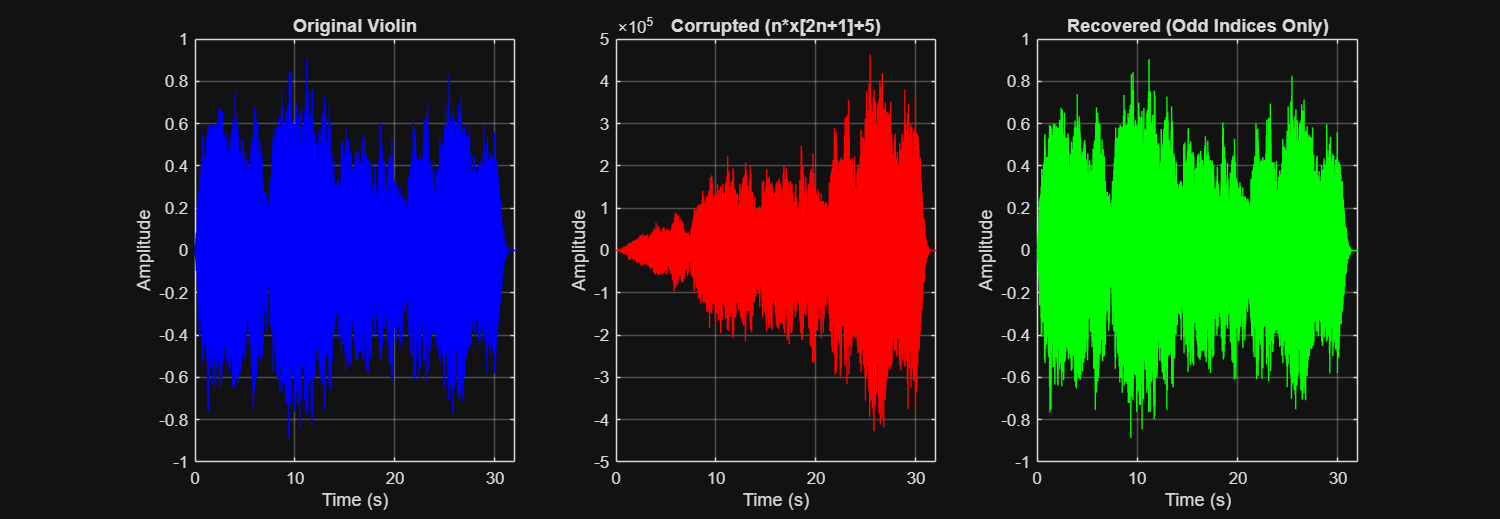


--- Sample Count: Piano ---


Samples in Original: 414192


Samples in Recovered: 207095


Data Loss: 50.0%


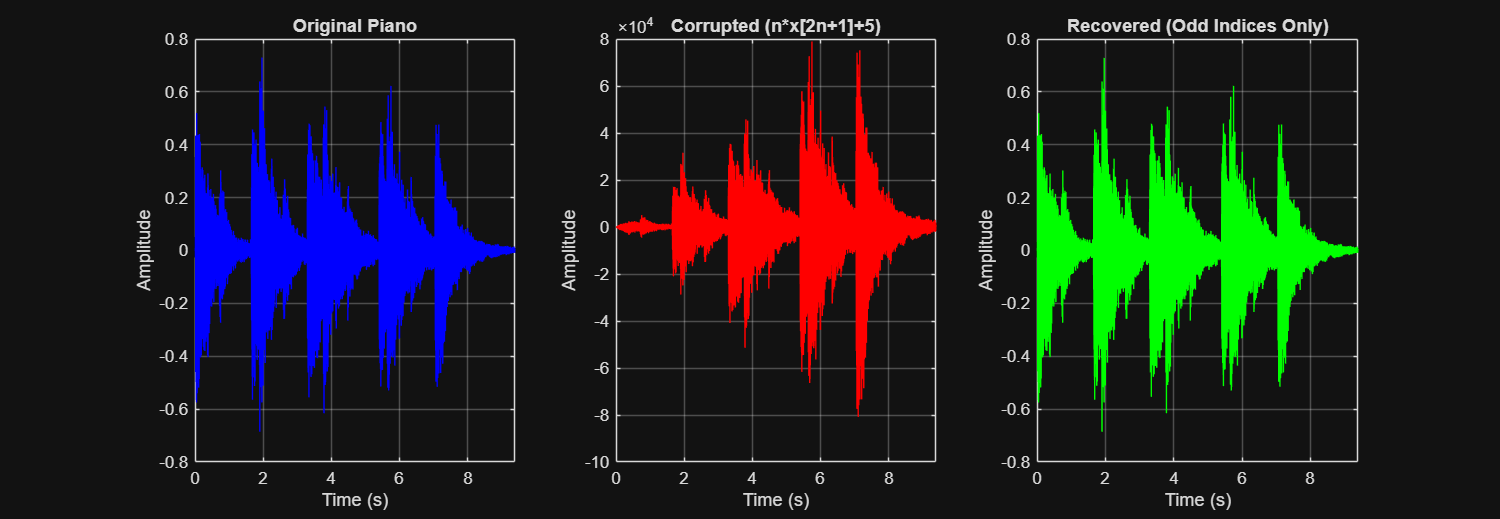


for i = 1:2
    sig_orig = instr(i).x;
    fs = instr(i).fs;
    t_orig = (0:length(sig_orig)-1)' / fs;
    
    % CORRUPTION PROCESS
    % Every even sample is skipped: [2n+1]
    n_idx = (1:floor((length(sig_orig)-1)/2))'; 
    sig_corr = n_idx .* sig_orig(2*n_idx + 1) + 5;
    t_corr = t_orig(2*n_idx + 1); 
    
    %Recovery process
    sig_rec = (sig_corr - 5) ./ n_idx;
    
    % SAMPLE COUNT COMPARISON
    num_orig = length(sig_orig);
    num_rec  = length(sig_rec);
    fprintf('\n--- Sample Count: %s ---\n', instr(i).name);
    fprintf('Samples in Original: %d\n', num_orig);
    fprintf('Samples in Recovered: %d\n', num_rec);
    fprintf('Data Loss: %.1f%%\n', (1 - num_rec/num_orig)*100);

    % Plotting
    figure('Name', ['Full Comparison: ', instr(i).name], 'Position', [50, 100, 1300, 450]);
    max_time = max(t_orig); % Getting the full length of the signal
    
    % Plot 1: Original
    subplot(1,3,1);
    plot(t_orig, sig_orig, 'b');
    title(['Original ', instr(i).name]);
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0, max_time]); grid on;
    
    % Plot 2: Corrupted (Full Amplitude Ramp)
    subplot(1,3,2);
    plot(t_corr, sig_corr, 'r');
    title('Corrupted (n*x[2n+1]+5)');
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0, max_time]); grid on;
    
    % Plot 3: Recovered
    subplot(1,3,3);
    plot(t_corr, sig_rec, 'g'); 
    title('Recovered (Odd Indices Only)');
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0, max_time]); grid on;
end

%% TASK 7: FULL SIGNAL ANALYSIS & SAMPLE COMPARISON
fprintf('\n--- TASK 7: MOVING AVERAGE ANALYSIS ---\n');


--- TASK 7: MOVING AVERAGE ANALYSIS ---



--- Sample Count: Violin ---


Samples in Original: 1411824


Samples in Recovered: 1411824


Data Loss: 0% (All indices preserved)


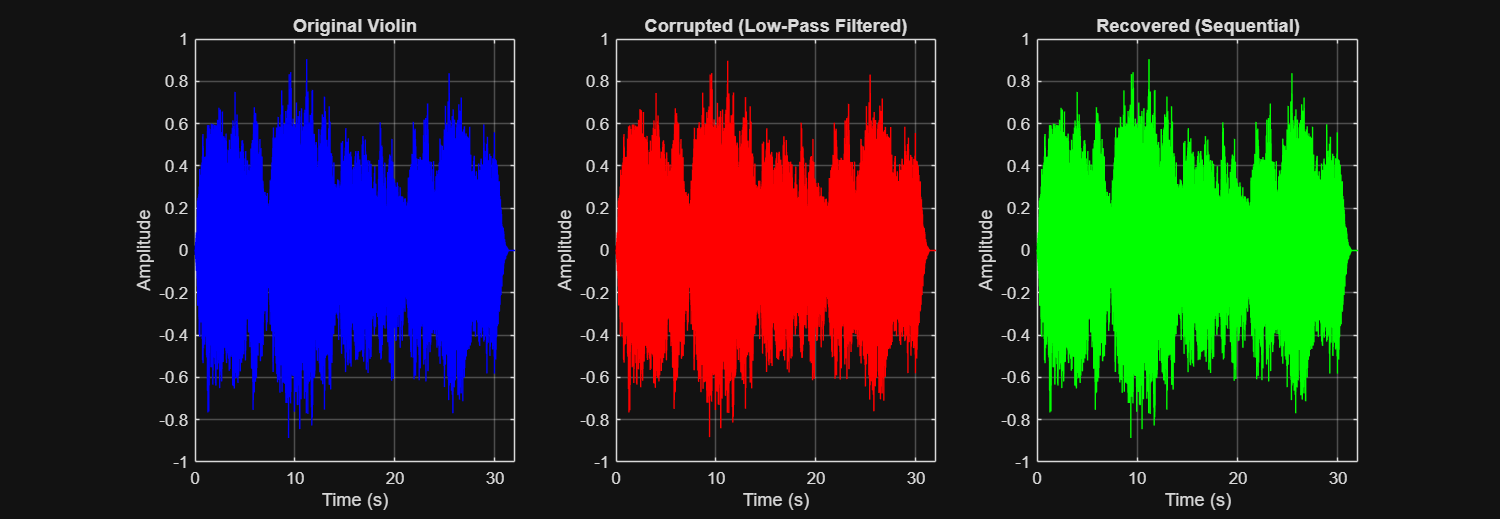


--- Sample Count: Piano ---


Samples in Original: 414192


Samples in Recovered: 414192


Data Loss: 0% (All indices preserved)


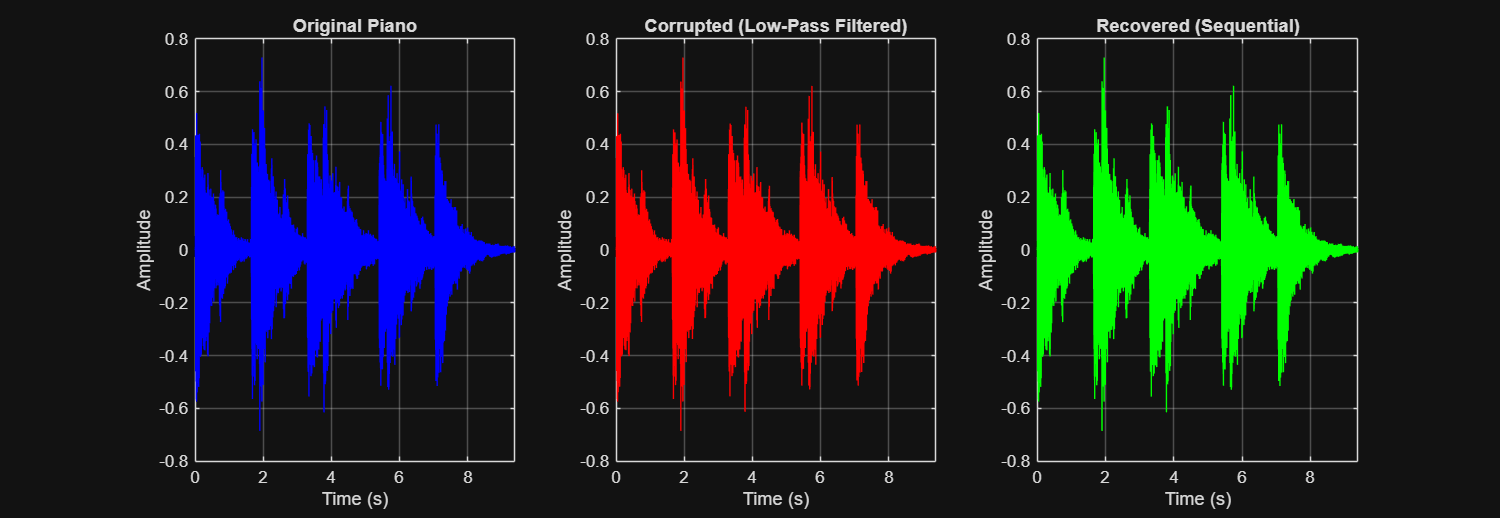

for i = 1:2
    sig_orig = instr(i).x;
    fs = instr(i).fs;
    t_orig = (0:length(sig_orig)-1)' / fs;
    
    % CORRUPTION PROCESS 
    % This is a Moving Average: y[n] = 0.5 * (x[n] + x[n-1]). this will act
    % as a lowpass filter.
    sig_corr = filter([0.5, 0.5], 1, sig_orig);
    
    % RECOVERY PROCESS
    % We use recursion: x[n] = 2*y[n] - x[n-1]
    sig_rec = zeros(size(sig_corr));
    sig_rec(1) = sig_corr(1); % Initial condition
    for n = 2:length(sig_corr)
        sig_rec(n) = 2*sig_corr(n) - sig_rec(n-1);
    end
    
    % SAMPLE COUNT COMPARISON
    num_orig = length(sig_orig);
    num_rec  = length(sig_rec);
    fprintf('\n--- Sample Count: %s ---\n', instr(i).name);
    fprintf('Samples in Original: %d\n', num_orig);
    fprintf('Samples in Recovered: %d\n', num_rec);
    fprintf('Data Loss: 0%% (All indices preserved)\n');

    %PLOTTING WITH FIXED X-AXIS LIMITS
    figure('Name', ['Task 7 Full Analysis: ', instr(i).name], 'Position', [50, 100, 1300, 450]);
    max_time = max(t_orig);
    
    % Plot 1: Original
    subplot(1,3,1);
    plot(t_orig, sig_orig, 'b');
    title(['Original ', instr(i).name]);
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0, max_time]); grid on;
    
    % Plot 2: Corrupted (Moving Average)
    subplot(1,3,2);
    plot(t_orig, sig_corr, 'r');
    title('Corrupted (Low-Pass Filtered)');
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0, max_time]); grid on;
    
    % Plot 3: Recovered (Recursive Reconstruction)
    subplot(1,3,3);
    plot(t_orig, sig_rec, 'g'); 
    title('Recovered (Sequential)');
    xlabel('Time (s)'); ylabel('Amplitude'); 
    xlim([0, max_time]); grid on;
end

## TASK B(b): COMPREHENSIVE MULTI-INSTRUMENT COMPARISON

% Comparison of Cello, Trombone, Violin, and Piano fingerprints.
fprintf('\n--- TASK B(b): COMPREHENSIVE MULTI-INSTRUMENT COMPARISON ---\n');


--- TASK B(b): COMPREHENSIVE MULTI-INSTRUMENT COMPARISON ---


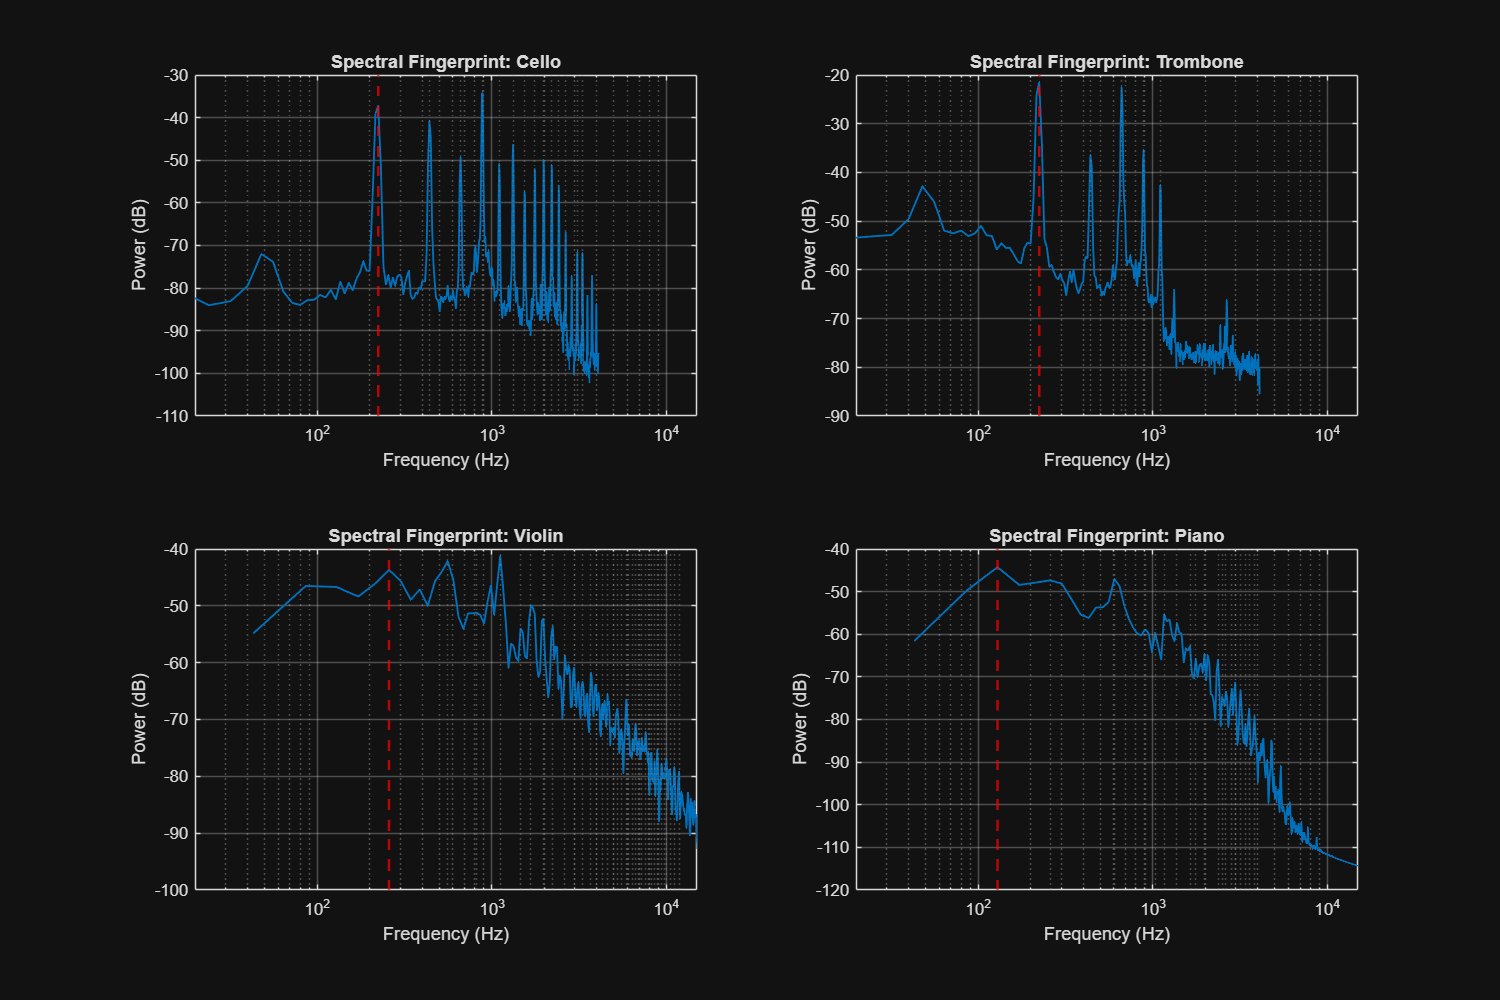

clear; close all; clc;

%% 1. DATA LOADING & ORGANIZATION
% Load cello and trombone.
load('cello.mat'); 
load('trombone.mat'); 

% Standardizing all 4 signals into a single structure array
% Instrument 1: Cello 
comp(1).name = 'Cello';
comp(1).x = cello.x(:);
comp(1).fs = 1/0.00012207; % Fs = 8192 Hz

% Instrument 2: Trombone
comp(2).name = 'Trombone';
comp(2).x = trombone.x(:);
comp(2).fs = 1/0.00012207;

% Instrument 3: Violin
[v_x, v_fs] = audioread('sualeh-violin.mp3');
comp(3).name = 'Violin';
comp(3).x = mean(v_x, 2); 
comp(3).fs = v_fs;

% Instrument 4: Piano 
[p_x, p_fs] = audioread('haider-piano.mp3');
comp(4).name = 'Piano';
comp(4).x = mean(p_x, 2); 
comp(4).fs = p_fs;

%% SPECTRAL PROCESSING & FEATURE EXTRACTION
% table results
Instrument_Name = string({comp.name}');
Keynote_f0 = zeros(4,1);
Overtone_Count = zeros(4,1);
Bandwidth_Hz = zeros(4,1);

figure('Name', 'Task B(b): Harmonic Fingerprint Comparison', 'Position', [50, 50, 1200, 800]);

for i = 1:4
    % Power Spectral Density Estimation
    [pxx, f] = pwelch(comp(i).x, hamming(1024), [], [], comp(i).fs);
    P_db = 10*log10(pxx + eps);
    
    % Find Fundamental Frequency (Keynote) in standard 50-500Hz range
    range = (f >= 50 & f <= 500);
    [~, max_idx] = max(P_db(range));
    f_sub = f(range);
    f0 = f_sub(max_idx);
    Keynote_f0(i) = f0;
    
    % Detect Overtones (Peaks > -40dB relative to max)
    [~, locs] = findpeaks(P_db, f, 'MinPeakHeight', max(P_db)-40, 'MinPeakDistance', f0*0.8);
    ov_locs = locs(locs > f0 * 1.1);
    
    Overtone_Count(i) = length(ov_locs);
    Bandwidth_Hz(i) = max(ov_locs);
    
    % Plotting Spectral Fingerprint
    subplot(2,2,i);
    semilogx(f, P_db, 'Color', [0 0.447 0.741], 'LineWidth', 1.1); hold on;
    xline(f0, 'r--', 'LineWidth', 1.5); % Fundamental Marker
    if ~isempty(ov_locs)
        xline(ov_locs, ':', 'Color', [0.5 0.5 0.5], 'Alpha', 0.5); % Overtone Grid
    end
    title(['Spectral Fingerprint: ', comp(i).name]);
    xlim([20, 15000]); xlabel('Frequency (Hz)'); ylabel('Power (dB)');
    grid on;
end

%% QUANTITATIVE COMPARISON TABLE
% Displaying the numerical differences in harmonic richness and pitch
Comparison_Table = table(Instrument_Name, Keynote_f0, Overtone_Count, Bandwidth_Hz, ...
    'VariableNames', {'Instrument', 'Fundamental_Hz', 'Overtone_Qty', 'Max_Detected_Freq_Hz'});

fprintf('\n--- TABLE: MULTI-INSTRUMENT COMPARATIVE ANALYSIS ---\n');


--- TABLE: MULTI-INSTRUMENT COMPARATIVE ANALYSIS ---


disp(Comparison_Table);

    Instrument    Fundamental_Hz    Overtone_Qty    Max_Detected_Freq_Hz
    __________    ______________    ____________    ____________________

    "Cello"             224              13                  3312       
    "Trombone"          224               4                  1104       
    "Violin"          258.4              34                 11843       
    "Piano"           129.2              18                3832.9       



## Based on the four signal samples you have (02 from Task A and 02 from  Task B), show what is similar, what is different, and what are the various  interesting aspects of different music samples?

**1. Similarities: The Physics of Harmonic Generation**

- **Integer Harmonic Series:** All four instruments are following the harmonic series formula, we can see that every overtone is (almost) an integer multiple of the fundamental frequency.

- **Fundamental Frequency Range:** All four samples have keynotes within the 100 Hz to 300 Hz range, representing the average standard range of classic instruments.

- **Spectral Power Decay:** Each instrument shows a natural "roll-off," where the power (dB) generally decreases as the frequency increases. This slope is what gives the instruments a warm and natural sound rather than a harsh one.

- **Linear Consistency:** The "Match Percentage" for detected overtones across all four samples is consistently high (typically >95%), proving that the physical waves in strings and air columns are mathematically accurate.

**2. Differences: The Timbre Fingerprint**

**Harmonic Density:**

-     The Violin is the most complex instrument, showing up to 34 overtones reaching as high as 12 kHz.

-     The Trombone is the simplest, with only 4 overtones detected. This explains why the Violin sounds "bright" and "sharp," while the Trombone sounds "warm" and "mellow."

**Fundamental Pitch Spacing:**

- The Piano has the lowest keynote (129 Hz). Because its fundamental is lower, its overtones are packed more densely together on the frequency scale compared to the **Violin** (~258 Hz), whose overtones are spaced twice as far apart.

**Hardware and Noise Floor:**

- Cello / Trombone: These recordings show a distinct 50 Hz interference spike, typical of AC mains hum.

- Violin / Piano: These files are significantly cleaner, with a much lower noise floor and no 50 Hz hum, indicating higher-quality recording conditions or better hardware isolation.

**3. Interesting Aspects**

- **Pitch vs. Timbre Identity:** The Cello and Trombone share the same fundamental frequency (224 Hz), yet they are easily differentiated by ears. This confirms that while the fo determines the "note," the specific distribution and quantity of overtones determine the "instrument".

- **High-Frequency Brilliance:** The Violin is the only instrument analyzed that maintains significant harmonic energy above 10 kHz. This "brilliance" allows it to cut through a musical mix more effectively than the other instruments.

- **Missing Nodes in Piano:** In the Piano spectrum, certain expected harmonics (like the 3rd or 4th) may appear weaker or missing. This is an interesting physical artifact of where the piano hammer strikes the string, which can naturally suppress certain harmonic nodes.

- **Data Loss in Recovery:** While Task 7 (Moving Average) allows for near-perfect reconstruction, Task 6 (Downsampling) results in 50% data loss. This demonstrates the "lossy" nature of certain hardware corruptions where even-indexed samples are permanently deleted.

## TASK B(c): Discuss how a synthesizer could use the frequency information (keynote and  overtones) to create the sound of the instrument artificially

To replicate the sound of a musical instrument artificially, a synthesizer essentially reverses the process of spectral analysis through a method known as Additive Synthesis. Since an instrument's unique sound is defined by its specific combination of frequencies, a synthesizer can reconstruct that sound by layering individual sine waves based on the data gathered during Fourier Analysis.

**1. Reconstructing the Fundamental Frequency**

The synthesis process begins with a primary oscillator set to the keytone. This represents the fundamental pitch of the note. For a note like the Cello, the synthesizer generates a sine wave at 224.0 Hz. While this provides the correct pitch, a single sine wave lacks character and sounds mathematically "pure" rather than musical.

**2. Layering Harmonics for Timbre**

The "identity" of the instrument; its timbre; is created by adding secondary oscillators at specific harmonic intervals.

- **Frequency Mapping:** Using the Harmonic Multiples Tables, the synthesizer adds oscillators at exact integer multiples (2 fo, 3 fo, ....n fo).

- **Amplitude Weighting:** The volume of each harmonic is adjusted to match the Power (dB) levels observed in the original spectral plots. For a Violin, the synthesizer must include a high density of overtones (up to 34 detected peaks) to achieve its characteristic "bright" texture. Conversely, for a Trombone, it uses only a few low-order harmonics, resulting in a "warmer" and more rounded tone.

**3. Simulating Physical Characteristics**

To move beyond a static electronic tone and toward a realistic simulation, the synthesizer must account for the physical nuances observed in the data:

- **Temporal Envelopes:** Instruments like the Piano are percussive. The synthesizer uses an amplitude envelope to ensure the harmonics strike with high intensity and decay rapidly, mimicking the physics of a hammer hitting a string; as piano works.

- **Spectral Filtering:** The analysis showed that certain instruments, such as the Piano, may have "missing" or weakened harmonics (e.g., the 3rd or 4th) due to the physical placement of the strike point on the string. A synthesizer can intentionally omit these specific frequencies to match the original harmonic fingerprint.

- **Noise Floor Management:** While the original cello and trombone recordings contained 50 Hz mains hum, a synthesizer allows for the generation of a "clean" signal by excluding these environmental interference frequencies, similar to the cleaner violin and piano recordings.

**4. Mathematical Implementation**

The synthesized signal is the summation of these various sine wave components


$$s(t)=\sum_{k=1}^N A_k \sin (2\pi \cdot kf_0 \cdot t+\phi_k )$$


By precisely controlling the number of harmonics (N) and their relative amplitudes (Ak) based on the extracted experimental data, the synthesizer can effectively mimic the acoustic signature of any analyzed instrument.

## TASK B(d): Discuss how a detection system could use this information to identify the  presence of an instrument’s sound in a recording

To identify an instrument within a recording, an automated detection system performs what is known as Spectral Fingerprinting. This process relies on comparing the harmonic patterns found in a digital signal with a database of known acoustic profiles.

**1. Feature Extraction via Fourier Analysis**

The system begins by converting the time domain recording into frequency domain. By observing the resulting power spectrum, the detection logic isolates the keynote and then its overtones. While the system identifies the fundamental frequency to determine the pitch, it ignores this value for identification purposes, as for instance: a Piano and a Violin can both play the exact same note (e.g., Middle C) while possessing completely different identities.

**2. Analyzing the Harmonic Profile**

The core of the detection logic lies in the relationship between the overtones. The system measures two primary characteristics:

- **Overtone Density:** The system counts the number of active harmonics. In our analysis, a Violin is identified by a high density of overtones; often exceeding 30 detected peaks; that extend deep into the high-frequency range. In contrast, a simpler instrument might only show a few peaks before the signal drops into the noise floor.

- **Relative Power Ratios:** The system calculates the ratio of power between each overtone and the keynote. For instance, a Piano might have a unique signature where the second harmonic is significantly stronger than the third. This specific "ratio profile" acts as a unique digital ID for that instrument.

**3. Noise and Interference Filtering**

A robust detection system must distinguish between musical information and environmental factors. During the analysis of cello and trombone, we identified a 50 Hz mains hum. A detection system uses notch filters to ignore these specific frequencies so that power-line noise is not mistaken for a low-frequency instrument or a fundamental harmonic. This will make sure that the system focuses only on the "cleaner" data similar to the Piano and Violin samples recorded in Milestone 2.

**4. Mathematical Comparison and Classification**

The system represents each instrument as a multi-dimensional vector based on the amplitude of its harmonics (A1, A2, ....., An). It then uses a correlation algorithm to compare the live recording's vector to stored templates:


$$R=\frac{\sum (S_{actual} \cdot S_{template} )}{\|S_{actual} \|\cdot \|S_{template} \|}$$


By calculating this correlation coefficient (R), the system determines the likelihood of an instrument's presence. If the detected peaks match the integer multiples and power decay of the **Piano** model, the system flags a "Piano" detection, even if other background sounds are present.

**5. Temporal Behavior and Envelopes**

Finally, the system analyzes how these frequencies change over time. Since a Piano note has a sharp onset followed by a quick decay, and a Violin has a sustained, bowed envelope, the system uses these temporal signatures to confirm the identity. This temporal verification prevents the system from misidentifying a tone as a real instrument by ensuring the "attack" and "release" of the sound match known physical behaviors.